#### EX 3-1 数值类型矩阵

1. 浮点型与整型

% 赋值a为2的数值类型
a = 2

a = 2

class(a)

ans = 'double'

% 定义变量b为2但不输出
b = int8(a)

b = int8
2

class(b)

ans = 'int8'

% 浮点型判断
c = a == 2*pi/3.14

c = logical
   0


d = abs(a-2*pi/3.14)<0.1

d = logical
   1


% 整数判断
e = b == 2*pi/3.14

e = logical
   0


f = b == int8(2*pi/3.14)

f = logical
   1


2. 复数矩阵

% 复数赋值
g = 3+4i

g = 3.0000 + 4.0000i

% 求复数g的模
h = abs(g)

h = 5

% 复数矩阵
l = [g 2*g g*g]

l =    3.0000 + 4.0000i   6.0000 + 8.0000i  -7.0000 +24.0000i


#### EX 3-2 字符型矩阵

1. 字符矩阵

% 赋值字符矩阵
a = 'x'

a = 'x'

b = 'yz'

b = 'yz'

class(a)

ans = 'char'

% 字符矩阵拼接
c = [a b;'uvw']

c = 2×3 char 数组
    'xyz'
    'uvw'


% 求字符矩阵的规模
d = size(c)

d =      2     3


2. 字符串矩阵

% 赋值字符串矩阵
e = "Hello, "

e = "Hello, "

f = string('World!')

f = "World!"

class(e)

ans = 'string'

% 字符串矩阵组合
g = [e,f]

g = 1×2 string 数组
    "Hello, "    "World!"


h = strlength(g)

h =      7     6


% 字符串矩阵拼接
l = join(g)

l = "Hello,  World!"

m = strlength(l)

m = 14

#### EX 3-3 符号型矩阵

1. 符号变量及矩阵

% 定义符号变量
syms x
% 符号表达式
y1 = x+5*x

$$y1 = 6\,x$$

classY1 = class(y1)

classY1 = 'sym'

sizeY1 = size(y1)

sizeY1 =      1     1


% 符号表达式矩阵
y2 = x^2+3*x

$$y2 = x^{2}+3\,x$$

y = [y1; y2]

$$y = \left(\begin{array}{c} 6\,x\\ x^{2}+3\,x \end{array}\right)$$

sizeY = size(y)

sizeY =      2     1


% 简化符号表达式形式
simY = simplify(y)

$$simY = \left(\begin{array}{c} 6\,x\\ x\,\left(x+3\right) \end{array}\right)$$

2. 简单应用举例

syms a b c d
% 用符号代表矩阵中的元素
A = [a b; c d]

$$A = \left(\begin{array}{cc} a & b\\ c & d \end{array}\right)$$

% 求矩阵的逆
invA = inv(A)

$$invA = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

#### EX 3-4 元胞数组

1. 创建元胞数组

% 元胞数组整体输入
cellA = {1, 'text'; zeros(2,3), {11; 22}}

cellA = 2×2 cell 数组
    {[       1]}    {'text'  }
    {2×3 double}    {2×1 cell}


celldisp(cellA)

 
cellA{1,1} =
 
     1

 
 
cellA{2,1} =
 
     0     0     0
     0     0     0

 
 
cellA{1,2} =
 
text
 
 
cellA{2,2}{1} =
 
    11

 
 
cellA{2,2}{2} =
 
    22

 


% 元胞数组按元素赋值
cellB(2,2) = {5}

cellB = 2×2 cell 数组
    {0×0 double}    {0×0 double}
    {0×0 double}    {[       5]}


% 快速创建空元胞数组
cellC = cell(2,3)

cellC = 2×3 cell 数组
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}


2. 访问元胞数组中的数据

% 使用小括号，访问的是元素，即元胞
a = cellA(1,1)

a = 1×1 cell 数组
    {[1]}


% 使用大括号，访问的元素中的数据
b = cellA{1,1}

b = 1

c = cellA{1,2}

c = 'text'

3. 元胞数组转化为矩阵

cellD = {[1 2]; [3 4]}

cellD = 2×1 cell 数组
    {1×2 double}
    {1×2 double}


matD = cell2mat(cellD)

matD =      1     2
     3     4


#### EX 3-5 结构体

1. 创建结构体

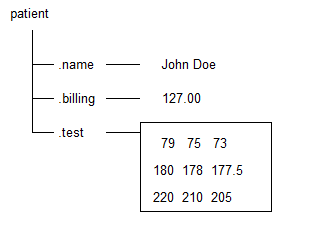

patient.name = 'John Doe';
patient.billing = 127.00;
patient.test = [79, 75, 73; ...
    180, 178, 177.5; 220, 210, 205];
patient, patient.name

patient = 包含以下字段的 struct :
       name: 'John Doe'
    billing: 127
       test: [3×3 double]


ans = 'John Doe'

2. 结构体数组

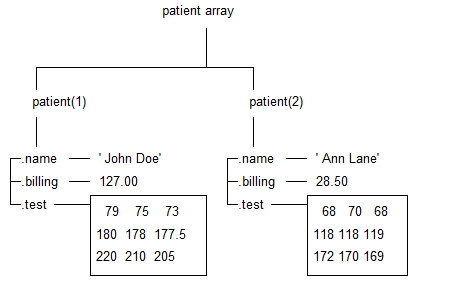

patient(2).name = 'Ann Lane';
patient(2).billing = 28.50;
patient(2).test = [68, 70, 68; 118, 118, 119; 172, 170, 169];
patient, patient(2), patient(2).name

patient = 包含以下字段的 1×2 struct 数组:
    name
    billing
    test


ans = 包含以下字段的 struct :
       name: 'Ann Lane'
    billing: 28.5000
       test: [3×3 double]


ans = 'Ann Lane'

#### EX 3-6 表

1. 创建表

% 清空工作区
clear
% 载入内存变量
load patients
% 取变量建立表
tablePatients = table(Gender, Age, Weight, Smoker)

tablePatients = 100×4 table
      Gender      Age    Weight    Smoker
    __________    ___    ______    ______

    {'Male'  }    38      176      true  
    {'Male'  }    43      163      false 
    {'Female'}    38      131      false 
    {'Female'}    40      133      false 
    {'Female'}    49      119      false 
    {'Female'}    46      142      false 
    {'Female'}    33      142      true  
    {'Male'  }    40      180      false 
    {'Male'  }    28      183      false 
    {'Female'}    31      132      false 
    {'Female'}    45      128      false 
    {'Female'}    42      137      false 
    {'Male'  }    25      174      false 
    {'Male'  }    39      202      true  
    {'Female'}    36      129      false 
    {'Male'  }    48      181      true  


2. 表索引

% 提取表的一部分——数字索引
tablePatients(1:3,:)

ans = 3×4 table
      Gender      Age    Weight    Smoker
    __________    ___    ______    ______

    {'Male'  }    38      176      true  
    {'Male'  }    43      163      false 
    {'Female'}    38      131      false 


% 制作命名索引
tablePatients.Properties.RowNames = LastName;
% 提取表的一部分——命名索引
tablePatients({'Smith','Johnson'},{'Gender','Smoker'})

ans = 2×2 table
                Gender     Smoker
               ________    ______

    Smith      {'Male'}    true  
    Johnson    {'Male'}    false 


3. 表存储

% 存储为文本文档
writetable(tablePatients, 'tablePatients.txt')
% 存储为电子表格
writetable(tablePatients,'tablePatients.csv')

#### EX 3-7 矩阵索引操作

1. 冒号与end关键字

a = [1 2 3; 4 5 6]

a =      1     2     3
     4     5     6


% 索引方式取矩阵的一部分
b = a(:,1:2)

b =      1     2
     4     5


c = a(:,[1 3])

c =      1     3
     4     6


% 取矩阵最后一行最后一列的元素
d = a(end,end-1)

d = 5

2. 单索引与角标索引

% 单索引整理
e = a(:)

e =      1
     4
     2
     5
     3
     6


reshape(e,size(a))

ans =      1     2     3
     4     5     6


% 取2行3列位置的单索引
index = sub2ind(size(a),2,3)

index = 6

% 验证两者是否相同
e(index) == a(2,3)

ans = logical
   1


% 反算角标索引
[sub1, sub2] = ind2sub(size(a),index)

sub1 = 2

sub2 = 3

3. 局部赋值

f = zeros(2,4)

f =      0     0     0     0
     0     0     0     0


% 取矩阵的一部分赋值
f(1,2:4) = [1 2 3]

f =      0     1     2     3
     0     0     0     0


#### EX 3-8 矩阵逻辑操作

1. 逻辑判断式作索引

a = [1 4 2; 4 2 6]

a =      1     4     2
     4     2     6


% 将大于3的位置标记为1
b = a>3

b = 2×3 logical 数组
   0   1   0
   1   0   1


% 提取a中大于3的元素 - 列向量形式
c = a(a>3)

c =      4
     4
     6


% aa:将a中不大于3的位置赋值为0
aa = a;
aa(~b) = 0

aa =      0     4     0
     4     0     6


2. 矩阵整体逻辑判断

% 普通矩阵转化为逻辑矩阵
b = logical(a-2)

b = 2×3 logical 数组
   1   1   0
   1   0   1


% 判断逻辑矩阵b是否全为真
allTrue = all(b(:))

allTrue = logical
   0


% 判断逻辑矩阵b是否至少一项为真
anyTrue = any(b(:))

anyTrue = logical
   1


% 判断两个矩阵是否完全一样
allSame = isequal(a,aa)

allSame = logical
   0


allSame2 = all(a(:)==aa(:))

allSame2 = logical
   0


3. 索引的逻辑提取

% 取a中大于3的元素的单索引
index = find(a>3)

index =      2
     3
     6


% 取a中第一个大于3的元素的单索引
firstIndex = find(a>3,1)

firstIndex = 2

% 取a中大于3的元素的角标索引
[sub1, sub2] = find(a>3)

sub1 =      2
     1
     2


sub2 =      1
     2
     3


#### EX 3-9 矩阵函数操作（1）

1. 基础信息

a = [1 4 2; 4 2 6]

a =      1     4     2
     4     2     6


% 求矩阵的维数
dimensionNumber = ndims(a)

dimensionNumber = 2

% 求矩阵的规模
sizeMatrix = size(a)

sizeMatrix =      2     3


% 求矩阵中元素总个数
elementNumber = numel(a)

elementNumber = 6

% 判断矩阵是否为空阵
isEmptyMatrix = isempty(a)

isEmptyMatrix = logical
   0


2. 向量生成

% 冒号生成
g = 2:2:7

g =      2     4     6


% 线性等距 从2到7
h = linspace(2,7,5)

h =     2.0000    3.2500    4.5000    5.7500    7.0000


% 对数等距 从10^2到10^7
l = logspace(2,7,5)

l = 	1.0e+07 *

    0.0000    0.0002    0.0032    0.0562    1.0000


3. 矩阵生成

% 冒号生成
x = 1:3; y = 2:4;
% 二维和三维网格
[X, Y] = meshgrid(x, y)

X =      1     2     3
     1     2     3
     1     2     3


Y =      2     2     2
     3     3     3
     4     4     4


% N 维空间中的矩形网格
z = 3:5;
[X, Y, Z] = ndgrid(x, y, z);

#### EX 3-10 矩阵函数操作（2）

1. 对数组元素排序

a = [1 3 7 5]

a =      1     3     7     5


sort(a)

ans =      1     3     5     7


% 矩阵所有元素沿第2维度（行）的排序元素
b = [1 2 3; 2 6 4; 4 2 1]

b =      1     2     3
     2     6     4
     4     2     1


sort(b,2)

ans =      1     2     3
     2     4     6
     1     2     4


% 按第2列对行排序（行内不打散）
sortrows(b, 2)

ans =      1     2     3
     4     2     1
     2     6     4


2. 重新排列 N 维数组的维度

c = rand(3, 4, 5);
% 把第1维度与第3维度对换
d = permute(c,[3 2 1]);
sizeD = size(d)

sizeD =      5     4     3


3. 删除单一维度

e = rand(2, 1, 3);
f = squeeze(e)

f =     0.2551    0.6991    0.9593
    0.5060    0.8909    0.5472


4. 翻转向量

h = [1 2; 3 4]

h =      1     2
     3     4


h1 = fliplr(h) % 行向量翻转

h1 =      2     1
     4     3


5. 重构矩阵的形状

m = 1:28;
reshape(m, 4, 7)

ans =      1     5     9    13    17    21    25
     2     6    10    14    18    22    26
     3     7    11    15    19    23    27
     4     8    12    16    20    24    28


#### EX 3-11 矩阵函数操作（3）

1. 沿指定维度串联数组

a = ones(2,3);
b = zeros(2,3);
c = cat(2, a, b)

c =      1     1     1     0     0     0
     1     1     1     0     0     0


2.按指定的行数/列数重复指定的矩阵

d = [1 2; 0 1]

d =      1     2
     0     1


% 在两个维度上分别重复2次和3次
repmat(d, 2, 3)

ans =      1     2     1     2     1     2
     0     1     0     1     0     1
     1     2     1     2     1     2
     0     1     0     1     0     1


3. 智能扩展矩阵

e = [1 2; 3 4];
f = [1 0 0; 0 0 0]

f =      1     0     0
     0     0     0


g = [1 -1; 0 1]

g =      1    -1
     0     1


% Kronecker张量积
h = kron(e, f)

h =      1     0     0     2     0     0
     0     0     0     0     0     0
     3     0     0     4     0     0
     0     0     0     0     0     0


m = kron(e, g)

m =      1    -1     2    -2
     0     1     0     2
     3    -3     4    -4
     0     3     0     4


#### EX 3-12 矩阵算术运算

1. 算术处理

a = [-2 0 1; 2.1 3 1.5]

a =    -2.0000         0    1.0000
    2.1000    3.0000    1.5000


absA = abs(a) % 绝对值

absA =     2.0000         0    1.0000
    2.1000    3.0000    1.5000


roundA = round(a) % 四舍五入取整

roundA =     -2     0     1
     2     3     2


signA = sign(a) % 符号阵（1/0/-1）

signA =     -1     0     1
     1     1     1


2. 统计处理

minA = min(a) % 列向量元素的最小值 

minA =     -2     0     1


maxA = max(a) % 列向量元素的最大值 

maxA =     2.1000    3.0000    1.5000


meanA = mean(a) % 列向量元素的平均值 

meanA =     0.0500    1.5000    1.2500


sumA = sum(a) % 列向量元素总和 

sumA =     0.1000    3.0000    2.5000


3. 向量运算

b = [1 2 0]; c = [0 3 1];
% 向量b和c的内积 
dotBC = dot(b, c) 

dotBC = 6

% 向量b和c的外积
crossBC = cross(b, c) 

crossBC =      2    -1     3


% 求b向量的范数（欧氏长度/模）
normb = norm(b) 

normb = 2.2361

#### EX 3-13 矩阵逻辑运算

1. 逻辑矩阵

a = [-2 0 3];
% 判断矩阵a是否为逻辑矩阵
islogical(a)

ans = logical
   0


% 将a转换为逻辑矩阵
b = logical(a)

b = 1×3 logical 数组
   1   0   1


% 使用true/false赋值逻辑矩阵
c = [true true false]

c = 1×3 logical 数组
   1   1   0


2. 逻辑运算

andBC = b & c % 与

andBC = 1×3 logical 数组
   1   0   0


orBC = b | c % 或

orBC = 1×3 logical 数组
   1   1   1


notB = ~b % 非

notB = 1×3 logical 数组
   0   1   0


xorBC = xor(b, c) % 异或

xorBC = 1×3 logical 数组
   0   1   1


3. 逻辑判断

allB = all(b) % 所有为真

allB = logical
   0


anyB = any(b) % 任意为真

anyB = logical
   1


find(b) % 寻找真

ans =      1     3


4. 短路逻辑

shortAnd = 0 && 1 % 与

shortAnd = logical
   0


shortOr = 1 || 0 % 或

shortOr = logical
   1


#### EX 3-14 矩阵关系运算

1. 关系运算

a = [1 2 3]; b = [3 2 1];
a == b

ans = 1×3 logical 数组
   0   1   0


a >= b

ans = 1×3 logical 数组
   0   1   1


a ~= b

ans = 1×3 logical 数组
   1   0   1


% 确定两个矩阵完全相等
isEqual = isequal(a, b)

isEqual = logical
   0


2. 相邻关系 - 差分

c = [1 4 7 0 5 5 2 1]

c =      1     4     7     0     5     5     2     1


% 相邻元素的差：后一元素减前一元素
diffC = diff(c)

diffC =      3     3    -7     5     0    -3    -1


% 符号函数，明确大小关系
signDiffC = sign(diffC)

signDiffC =      1     1    -1     1     0    -1    -1


3. 点关系 - 距离

d = [1 2; 2 3; -1 0; 0 1]

d =      1     2
     2     3
    -1     0
     0     1


% 各点之间的欧氏距离
distVector = pdist(d)

distVector =     1.4142    2.8284    1.4142    4.2426    2.8284    1.4142


% 将距离向量化为更形象的矩阵
disMatrix = squareform(distVector)

disMatrix =          0    1.4142    2.8284    1.4142
    1.4142         0    4.2426    2.8284
    2.8284    4.2426         0    1.4142
    1.4142    2.8284    1.4142         0
